Consider the following optimization problem:


$$\left\lbrace \begin{array}{ll}
\textrm{minimize} & -x_1^2 +2x_1 +x_2^2 -2x_2 \\
s\ldotp t & x_1^2 -4\le 0\\
\; & x_2^2 -4\le 0
\end{array}\right.$$


close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

a) Do global optimal solutions exist? Why?

b) Is it a convex problem? Why?

It is a quadratic optimization problem and to prove that it is a convex optimization problem we need to show that both the objective function and the constraints are satisfy convexity properties:

- Objective Function: $f\left(x\right)=-x_1^2 +2x_1 +x_2^2 -2x_2$  

The objective function is quadratic convex minimization of the form: $f\left(x\right)=\frac{1}{2}x^T \textrm{Qx}+q^T x+b$ . To prove convexity, we need to show that the Hessian matrix Q is positive semidefinite. A matrix Q is positive semidefinite if the eigenvalues of Q are non-negative. 

- Constraints: 

-     
$$g_1 \left(x\right)=x_1^2 -4\le 0$$
 

-     
$$g_2 \left(x\right)=x_1^2 -4\le 0$$


The constraints in a quadratic convex minimization is presented on the form: $g_i \left(x\right)=\frac{1}{2}x^T A_i x+{a_i }^T x+c_i \le 0\;;\;\forall i=1,\ldotp \ldotp \ldotp ,m$  . To prove convexity, we need to show that the Hessian matrices $A_i$ are positive semidefinite.

% Objective Function
Q = [-4 0
      0 4];

% Inequality Constraints
A1 = [4 0
      0 0];

A2 = [0 0
      0 4];

eig(Q)

ans =     -4
     4


eig(A1)

ans =      0
     4


eig(A2)

ans =      0
     4


In convex optimization, the objective functions should be concave and the constraints should define convex sets. However, the problem is represented has a concave objective function and convex contraints, which still qualifies it as a convex problem. Therefore, the given problem is a convex optimization problem.

% Definition of objective function and constraints
objective_function = @(x1,x2) -x1.^2 + 2.*x1 + x2.^2 - 2.*x2;
constraint_1 = @(x1) real(sqrt(4 - x1.^2));
constraint_2 = @(x2) real(sqrt(4 - x2.^2));

% Create a grid of x1 and x2 values
x1 = linspace(-4, 4, 100);
x2 = linspace(-4, 4, 100);
[X1, X2] = meshgrid(x1, x2);

% Evaluate the objective function and constraints on the grid
X3 = objective_function(X1, X2);
C1 = constraint_1(x1);
C2 = constraint_2(x2);

% Create a 3D plot
figure;
surf(X1, X2, X3);

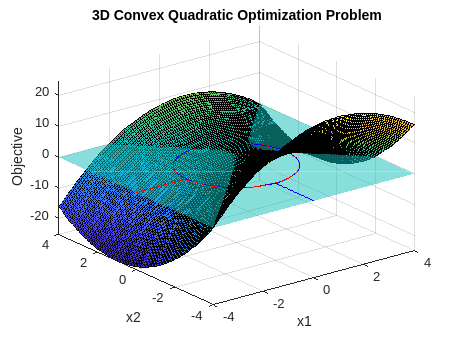

hold on;
plot3(x1, C1, zeros(size(x1)), 'r-');
plot3(x1, -C1, zeros(size(x1)), 'r-');
surf(X1, X2, zeros(size(X3)), 'FaceAlpha', 0.5, 'EdgeColor', 'none');
plot3(C2, x2, zeros(size(x2)), 'b-');
plot3(-C2, x2, zeros(size(x2)), 'b-');

% Set labels and title
xlabel('x1');
ylabel('x2');
zlabel('Objective');
title('3D Convex Quadratic Optimization Problem');

% Show the grid on the plot
grid on;

% Adjust the plot view for better visibility
view(3);

% Adjust the plot limits if needed
xlim([-4 4]);
ylim([-4 4]);
hold off

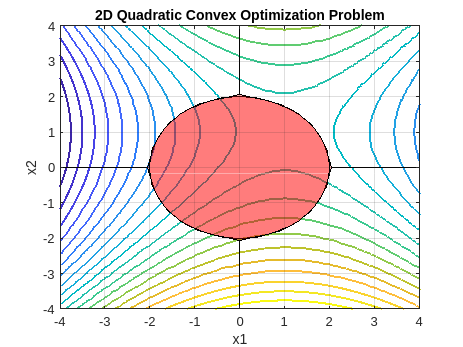

% Plot the objective function
figure;
contour(X1, X2, X3, 20, 'LineWidth', 1.5);
hold on;

% Plot the feasible region
fill([x1 fliplr(x1)], [C1 fliplr(-C1)], 'r', 'FaceAlpha', 0.3);
fill([C2 fliplr(-C2)],[x2 fliplr(x2)], 'r', 'FaceAlpha', 0.3);

% Set labels and title
xlabel('x1');
ylabel('x2');
title('2D Quadratic Convex Optimization Problem');

% Show the grid on the plot
grid on;

% Adjust the plot limits if needed
xlim([-4 4]);
ylim([-4 4]);

% Display the plot
hold off